clc, clear
rng('shuffle')
red = [255 0 0];
orange = [255 127 0];
yellow = [255 255 0];
green = [0 255 0];
blue = [0 0 255];
navy = [0 0 128];
purple = [160 32 240];

label = {'red' 'orange' 'yellow' 'green' 'blue' 'navy' 'purple'};
color = {red, orange, yellow, green, blue, navy, purple};

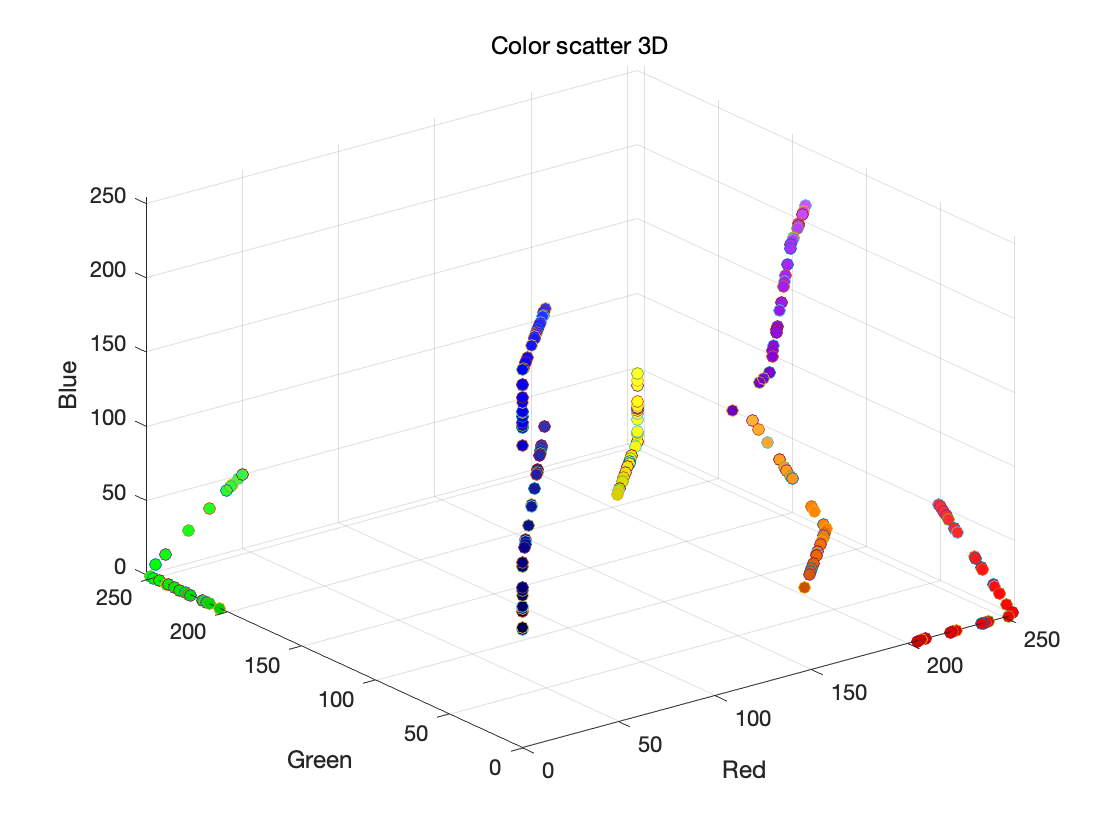

figure

for i = 1:length(label)
    cd('/Users/ansanghyeon/Documents/Private/University/3학년/2학기/인공지능시스템/과제/color')
    if isfolder(label{i}) == false
        mkdir(label{i})
    end
    cd(label{i})
    
    for j=1:30
        clearvars temp
        % true color 에서 20%의 변동폭을 가진다.
        value = 255 - randi([255*0.8 255]);
        
        if rand > 0.5
            %더하기
            temp = color{i} + value;
            idx = temp > 255;
            temp(idx) = 255;
        else
            %빼기
            temp = color{i} - value;
            idx = temp < 0;
            temp(idx) = 0;
        end
        
        hexStr = dec2hex(temp);
        str = strcat('#',hexStr(1,:),hexStr(2,:),hexStr(3,:));
%         figure(1)
%         rectangle('Position',[0 0 30 30],"FaceColor",str);
%         xticks([])
%         yticks([])
        
        scatter3(temp(1), temp(2), temp(3), 'MarkerFaceColor', str);
        hold on
%         saveas(gcf,strcat(string(j), '.png'))
    end
end
hold off
xlabel('Red')
ylabel('Green')
zlabel('Blue')
axis([0 255 0 255 0 255])
title('Color scatter 3D')